# Title & Project Overview (Steady state model)

% This Live Script documents the complete thermal design process for a radiator to cool the motor and motor controllers.

## Calculating Required Heat Rejection

import py.CoolProp.CoolProp.*
P_peak = 35000; % peak operating power of motor (W), F-MOT motor datasheet
efficiency = 0.93; % worst efficiency according to datasheet (%)
Q_motor = P_peak - efficiency*P_peak; % heat loss through water (W)
Q_motor_controller = 750; % max power dissipation according to datasheet, (W)
Q_target = Q_motor + Q_motor_controller; % (W)

## Fixed Inputs & Constants

% operating conditions 
mdot_coolant = 10; % mass flow rate of coolant (L/min), according to mc datasheet optimal at 10
T_coolant_in = 55; %(°C), max 70degC for motor controller 
T_air_in = 25; %ambient air temp of 25 assumed (°C)
v_air = 8.5; %velocity of air assumed to be 8.5m/s as used in old code, update according to data from past season

% fixed geometry (all in m)
d = 0.032; % common values added as options for depth of radiator 
H = 0.35; % range of 300-400mm added for height with steps of 25mm
a_tube = 0.002; % dimensions of rectangular tube, height as 2mm
b_tube = d; % width of tube taken equal to depth of radiator 
tube_pitch = 0.010; % height of tube(2mm) + fin space(8mm), used to calculate number of tubes 
D_h_tube = (4*a_tube*b_tube)/(2*(a_tube+b_tube)); % hydraulic diameter of tube
A_tube = a_tube*b_tube; % tube cross sectional area (m²)

% using data from the old code regarding fin dimensions
f_height = 0.008; % (8mm)
f_thickness = 0.00008; % (0.08mm)
% fin width same as radiator width 

% air properties at 25°C
T_air = 298.15; % Temperature in Kelvin (25°C)
P_air = 101325; % Pressure in Pascals (1 atm)

rho_air = PropsSI('D', 'T', T_air, 'P', P_air, 'Air'); % density (kg/m^3)
mu_air = PropsSI('V', 'T', T_air, 'P', P_air, 'Air'); % dynamic viscosity (Pa*s)
k_air = PropsSI('L', 'T', T_air, 'P', P_air, 'Air'); % thermal conductivity (W/m*K)
cp_air = PropsSI('C', 'T', T_air, 'P', P_air, 'Air'); % specific heat capacity (J/kg*K)
Pr_air = PropsSI('Prandtl', 'T', T_air, 'P', P_air, 'Air'); % Prandtl number

% parameter ranges 
fpi_range = linspace(8,25,18); %fins per inch
A_face_range = linspace(0.01, 0.20, 100); %radiator face area (m²)

## Water Properties as Functions of Temp

P_water = 101325; % 1 atm 
rho_water = PropsSI('D', 'T', 323.15, 'P', P_water, 'Water');
cp_water = PropsSI('C', 'T', 323.15, 'P', P_water, 'Water');
% density and thermal conductivity barely change over selected temp range,
% properties assumed at 50degC, needed for further calculation
mdot_coolant_kgs = (mdot_coolant*rho_water)/60000; %(L/min) to (kg/s)
deltaT = Q_target/(mdot_coolant_kgs*cp_water);
T_coolant_out = T_coolant_in - deltaT;
T_avg = (T_coolant_out+T_coolant_in)/2;
T_avg_K = T_avg + 273.15;
k_water = PropsSI('L', 'T', T_avg_K, 'P', P_water, 'Water');
mu_water = PropsSI('V', 'T', T_avg_K, 'P', P_water, 'Water');
Pr_water = PropsSI('Prandtl', 'T', T_avg_K, 'P', P_water, 'Water');

## Fin Density (m2/m3) to FPI (Fins per Inch)

% function [FPI] = sigma_to_fpi(sigma,f_height,f_thickness)
% p = 2*(f_height-f_thickness)/(sigma*f_height-2); %fin pitch (m)
% p_in = p/0.0254; %pitch (inches)
% FPI = 1/p_in;
% end

## Heat Transfer Calculations

Q_predicted = zeros(length(A_face_range), length(fpi_range)); %results matrix 
W_calculated = zeros(length(A_face_range), length(fpi_range)); %width matrix 

%water side convection heat transfer coefficient
n_tubes = floor(H/tube_pitch); %number of tubes 
mdot_tube = mdot_coolant_kgs/n_tubes; %mass flow rate per tube 
v_water = mdot_tube/(rho_water*A_tube); %velocity of water in each tube
Re_water = (rho_water*v_water*D_h_tube)/mu_water; 
if Re_water < 2300
    Nu_water = 3.66; %laminar 
else
    Nu_water = 0.023*(Re_water^0.8)*(Pr_water^0.3); %turbulent
end
h_water = (Nu_water*k_water)/D_h_tube; 

for i = 1:length(A_face_range)
    for j = 1:length(fpi_range)

        A_face = A_face_range(i);
        fpi = fpi_range(j);
        W_calculated(i,j) = A_face/H; %width stored for plotting
        W = A_face/H;
        
        %air side convection heat transfer coefficient  
        sigma_c = 1-((fpi*f_height*f_thickness)/0.0254+a_tube)/(a_tube+f_height); %contraction factor
        G_air = rho_air*v_air/sigma_c; % mass flux 
        f_spacing = 0.0254/fpi;
        D_h_fin = (4*f_spacing*f_height)/(2*(f_spacing+f_height)); %hydraulic diameter of fin channel
        Re_air = G_air*D_h_fin/mu_air; %reynolds numbers
        J_air = 0.174/(Re_air)^0.383; % Colburn j-factor 
        h_air = J_air*G_air*cp_air/(Pr_air^0.667);

        U = 1/((1/h_air)+(1/h_water)); %overall heat transfer coefficient

        %capacity rates 
        C_air = rho_air*v_air*cp_air*A_face;
        C_water = mdot_coolant_kgs*cp_water;
        C_min = min(C_air,C_water);
        C_max = max(C_air,C_water);
        C_star = C_min/C_max;

        %A_fins calculation
        A_primary = 2*d*W*(H/(a_tube+f_height)); % tube and air contact surface area 
        A_secondary = 2*f_height*d*fpi*W*(H/(a_tube+f_height))/0.0254; % fin and air contact surface area 
        k_fin = 237; %thermal conductivity of aluminium (fin material)
        % fin efficiency 
        m = sqrt(2*h_air/(k_fin*f_thickness));
        L_c = f_height/2;
        eta_f = tanh(m*L_c)/(m*L_c); 
        eta_0 = 1-(A_secondary/(A_primary+A_secondary))*(1-eta_f); %surface efficiency
        A_fins = eta_0*(A_primary+A_secondary); 

        NTU = (U*A_fins)/C_min; %number of transfer units 
        epsilon = 1-exp((NTU^0.22/C_star)*(exp(-C_star*NTU^0.78)-1)); 

        Q_predicted(i,j) = epsilon*C_min*(T_coolant_in-T_air_in);
    end
end

## Plotting Heat Rejected with Area and Fin Density

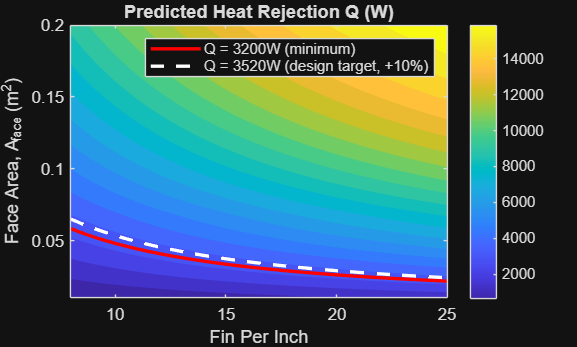

figure;
contourf(fpi_range, A_face_range, Q_predicted, 20, 'LineColor', 'none');
colorbar;
xlabel('Fin Per Inch');
ylabel('Face Area, A_{face} (m^2)');
title('Predicted Heat Rejection Q (W)');
hold on;

% Critical boundary - minimum requirement
contour(fpi_range, A_face_range, Q_predicted, [Q_target Q_target], 'r', 'LineWidth', 2);

% Adding a safety factor of 1.1 (considering all the worst case conditions
% assumed)
contour(fpi_range, A_face_range, Q_predicted, [Q_target*1.1 Q_target*1.1], 'w--', 'LineWidth', 2);

legend('', sprintf('Q = %gW (minimum)', Q_target), sprintf('Q = %gW (design target, +10%%)', Q_target * 1.1));
hold off;

## Plot Width of Radiator

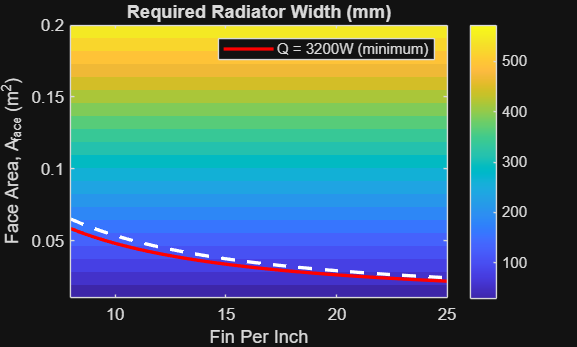

figure;
contourf(fpi_range, A_face_range, W_calculated*1000, 20, 'LineColor', 'none');
c = colorbar;
clim([min(W_calculated(:))*1000, max(W_calculated(:))*1000]);
xlabel('Fin Per Inch');
ylabel('Face Area, A_{face} (m^2)');
title('Required Radiator Width (mm)');
hold on;
contour(fpi_range, A_face_range, Q_predicted, [Q_target Q_target], 'r', 'LineWidth', 2);
contour(fpi_range, A_face_range, Q_predicted, [Q_target*1.1 Q_target*1.1], 'w--', 'LineWidth', 2);
legend('', sprintf('Q = %gW (minimum)', Q_target));
hold off;

## Extract exact A_face value and pressure drop at a given fpi

C = contourc(fpi_range, A_face_range, Q_predicted, [Q_target Q_target]);
fpi_contour = C(1,2:end);
A_face_contour = C(2,2:end);

[fpi_sorted, sort_idx] = sort(fpi_contour);
A_face_sorted = A_face_contour(sort_idx);

fpi_query = 18; %CHANGE HERE
A_face_min = interp1(fpi_sorted, A_face_sorted, fpi_query);
W_min = A_face_min/H;
f_darcy = 64/Re_water; % darcy friction factor for laminar flow 
P_drop_water = f_darcy*(W_min/D_h_tube)*(rho_water*v_water^2/2); %pressure drop across radiator 
fprintf('At fpi = %.0f, minimum A_face (Q=%.0fW) = %.4f m^2\n', fpi_query, Q_target, A_face_min);

At fpi = 18, minimum A_face (Q=3200W) = 0.0286 m^2


fprintf('At chosen fpi and A_face_min (H=%.0fmm), Pressure drop = %.2fPa\n', H*1000, P_drop_water);

At chosen fpi and A_face_min (H=350mm), Pressure drop = 7.17Pa



Q_target_margin = Q_target*1.1;
C2 = contourc(fpi_range, A_face_range, Q_predicted, [Q_target_margin Q_target_margin]);
fpi_contour2 = C2(1, 2:end);
A_face_contour2 = C2(2, 2:end);
[fpi_sorted2, sort_idx2] = sort(fpi_contour2);
A_face_sorted2 = A_face_contour2(sort_idx2);

A_face_design_target = interp1(fpi_sorted2, A_face_sorted2, fpi_query);
W_min_design = A_face_design_target/H;
P_drop_water_design = f_darcy*(W_min_design/D_h_tube)*(rho_water*v_water^2/2); %pressure drop across radiator
fprintf('At fpi = %.0f, design target A_face (Q=%.0fW, +10%%) = %.4f m^2\n', fpi_query, Q_target_margin, A_face_design_target)

At fpi = 18, design target A_face (Q=3520W, +10%) = 0.0318 m^2


fprintf('At chosen fpi and A_face_min (H=%.0fmm), Pressure drop = %.2fPa\n', H*1000, P_drop_water_design);

At chosen fpi and A_face_min (H=350mm), Pressure drop = 7.97Pa


## Checking dependency on H

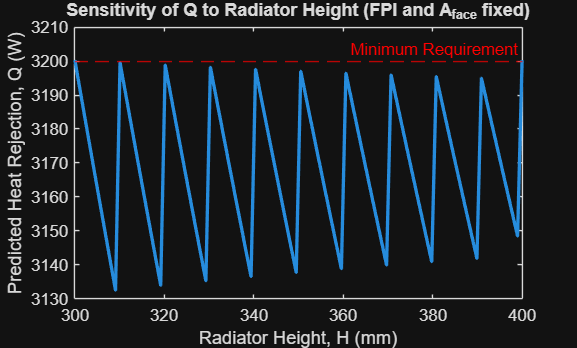

H_range = linspace(0.30, 0.40, 100); % team's given range: 30-40cm

A_face_fixed = A_face_min;% chosen design point
fpi_fixed = fpi_query;% chosen design point

Q_vs_H = zeros(size(H_range));

sigma_c_fixed = 1-((fpi_fixed*f_height*f_thickness)/0.0254+a_tube)/(a_tube+f_height);
G_air_fixed = rho_air*v_air/sigma_c_fixed;
f_spacing_fixed = 0.0254/fpi_fixed;
D_h_fin_fixed = (4*f_spacing_fixed*f_height)/(2*(f_spacing_fixed+f_height));
Re_air_fixed = G_air_fixed*D_h_fin_fixed/mu_air;
J_air_fixed = 0.174/(Re_air_fixed)^0.383;
h_air_fixed = J_air_fixed*G_air_fixed*cp_air/(Pr_air^0.667);

k_fin = 237; % thermal conductivity of aluminium (fin material)
L_c = f_height/2;

for m = 1:length(H_range)
    H = H_range(m);

    n_tubes = floor(H/tube_pitch); % this is what is changing 
    mdot_tube = mdot_coolant_kgs/n_tubes;
    v_water = mdot_tube/(rho_water*A_tube);
    Re_water = (rho_water*v_water*D_h_tube)/mu_water;
    if Re_water < 2300
        Nu_water = 3.66; %laminar 
    else
        Nu_water = 0.023*(Re_water^0.8)*(Pr_water^0.3); %turbulent
    end
    h_water = (Nu_water*k_water)/D_h_tube;

    U = 1/((1/h_air_fixed)+(1/h_water));

    W = A_face_fixed/H;
    A_primary = 2*d*W*n_tubes;
    A_secondary = 2*f_height*d*fpi_fixed*W*n_tubes/0.0254;
    m_fin = sqrt(2*h_air_fixed/(k_fin*f_thickness));
    eta_f = tanh(m_fin*L_c)/(m_fin*L_c);
    eta_0 = 1-(A_secondary/(A_primary+A_secondary))*(1-eta_f);
    A_total = eta_0*(A_primary+A_secondary);

    C_air = rho_air*v_air*cp_air*A_face_fixed;
    C_water = mdot_coolant_kgs*cp_water;
    C_min = min(C_air,C_water);
    C_max = max(C_air,C_water);
    C_star = C_min/C_max;

    NTU = (U*A_total)/C_min;
    epsilon = 1-exp((NTU^0.22/C_star)*(exp(-C_star*NTU^0.78)-1));

    Q_vs_H(m) = epsilon*C_min*(T_coolant_in-T_air_in);
end

plot(H_range*1000, Q_vs_H, 'LineWidth', 2)
xlabel('Radiator Height, H (mm)')
ylabel('Predicted Heat Rejection, Q (W)')
yline(Q_target, 'r--', 'Minimum Requirement')
title('Sensitivity of Q to Radiator Height (FPI and A_{face} fixed)')

% this plot shows us that given an area and fin density, varying height
% doesnt have a significant change in heat rejection so calculating heat
% according to fixed height of 350mm for the previous section was fine

## Checking dependency on coolant flow rate

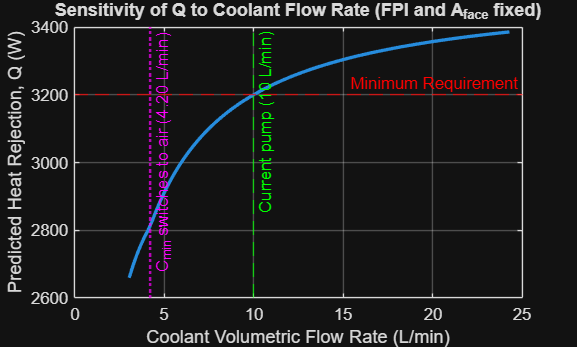

mdot_range_test = linspace(0.05, 0.40, 100);% (kg/s) or (3-24L/min), later changed to L/min to showcase in the graph

A_face_fixed2 = A_face_min;% chosen design point
fpi_fixed2 = fpi_query;% chosen design point
H_fixed = 0.35;% chosen design point

Q_vs_mdot = zeros(size(mdot_range_test));

n_tubes_fixed = floor(H_fixed/tube_pitch);

sigma_c_fixed2 = 1-((fpi_fixed2*f_height*f_thickness)/0.0254+a_tube)/(a_tube+f_height);
G_air_fixed2 = rho_air*v_air/sigma_c_fixed2;
f_spacing_fixed2 = 0.0254/fpi_fixed2;
D_h_fin_fixed2 = (4*f_spacing_fixed2*f_height)/(2*(f_spacing_fixed2+f_height));
Re_air_fixed2 = G_air_fixed2*D_h_fin_fixed2/mu_air;
J_air_fixed2 = 0.174/(Re_air_fixed2)^0.383;
h_air_fixed2 = J_air_fixed2*G_air_fixed2*cp_air/(Pr_air^0.667);

k_fin = 237; % thermal conductivity of aluminium (fin material)
L_c = f_height/2;
W_fixed2 = A_face_fixed2/H_fixed;
A_primary_fixed2 = 2*d*W_fixed2*n_tubes_fixed;
A_secondary_fixed2 = 2*f_height*d*fpi_fixed2*W_fixed2*n_tubes_fixed/0.0254;
m_fin2 = sqrt(2*h_air_fixed2/(k_fin*f_thickness));
eta_f2 = tanh(m_fin2*L_c)/(m_fin2*L_c);
eta_0_fixed2 = 1-(A_secondary_fixed2/(A_primary_fixed2+A_secondary_fixed2))*(1-eta_f2);
A_total_test = eta_0_fixed2*(A_primary_fixed2+A_secondary_fixed2);

for p = 1:length(mdot_range_test)
    mdot_coolant_test = mdot_range_test(p);

    % water side h (depends on mdot_coolant_test)
    mdot_tube = mdot_coolant_test/n_tubes_fixed;
    v_water = mdot_tube/(rho_water*A_tube);
    Re_water = (rho_water*v_water*D_h_tube)/mu_water;
    if Re_water < 2300
        Nu_water = 3.66; %laminar 
    else
        Nu_water = 0.023*(Re_water^0.8)*(Pr_water^0.3); %turbulent
    end
    h_water_test = (Nu_water*k_water)/D_h_tube;

    U_test = 1/((1/h_air_fixed2)+(1/h_water_test));

    C_air_test = rho_air*v_air*cp_air*A_face_fixed2;
    C_water_test = mdot_coolant_test*cp_water;
    C_min_test = min(C_air_test,C_water_test);
    C_max_test = max(C_air_test,C_water_test);
    C_star_test = C_min_test/C_max_test;

    NTU_test = (U_test*A_total_test)/C_min_test;
    epsilon_test = 1-exp((NTU_test^0.22/C_star_test)*(exp(-C_star_test*NTU_test^0.78)-1));

    Q_vs_mdot(p) = epsilon_test*C_min_test*(T_coolant_in-T_air_in);
end
%at lower mdot, cmin = cwater instead of cair so Q drastically increases in
%the start but diminishing returns as later cwater>cair so q = cmin*delta t
%gets a fixed cmin = cair, and delta t only changed by U which isnt
%affected much by water

V_dot_Lmin = (mdot_range_test ./ rho_water)*60000; % convert kg/s to L/min
mdot_crossover_kgs = rho_air*v_air*cp_air*A_face_fixed2/cp_water;
mdot_crossover_Lmin = mdot_crossover_kgs/rho_water*60000;
figure;
plot(V_dot_Lmin, Q_vs_mdot, 'LineWidth', 2)
xlabel('Coolant Volumetric Flow Rate (L/min)')
ylabel('Predicted Heat Rejection, Q (W)')
yline(Q_target, 'r--', 'Minimum Requirement')
xline(mdot_coolant, 'g--', sprintf('Current pump (%g L/min)', mdot_coolant))
xline(mdot_crossover_Lmin, 'm:', sprintf('C_{min} switches to air (%.2f L/min)', mdot_crossover_Lmin), 'LineWidth', 1.5)
title('Sensitivity of Q to Coolant Flow Rate (FPI and A_{face} fixed)')
grid on

## Testing min A_face at diff FPI

fpi_test_points = fpi_range;

C_q = contourc(fpi_range, A_face_range, Q_predicted, [Q_target Q_target]);
fpi_q = C_q(1, 2:end);
A_face_q = C_q(2, 2:end);
[fpi_q_sorted, idx] = sort(fpi_q);
A_face_q_sorted = A_face_q(idx);

fprintf('%-10s %-15s %-12s\n', 'FPI', 'A_face (m^2)', 'Width (mm)')

FPI        A_face (m^2)    Width (mm)  


for f = fpi_test_points
    A_face_at_s = interp1(fpi_q_sorted, A_face_q_sorted, f);
    W_at_s = A_face_at_s/H*1000;
    fprintf('%-10d %-15.4f %-12.1f\n', f, A_face_at_s, W_at_s)
end

8          0.0583          145.7       
9          0.0526          131.6       
10         0.0480          120.0       
11         0.0441          110.4       
12         0.0409          102.2       
13         0.0381          95.1        
14         0.0356          89.1        
15         0.0335          83.8        
16         0.0317          79.2        
17         0.0300          75.1        
18         0.0286          71.4        
19         0.0273          68.2        
20         0.0261          65.3        
21         0.0250          62.6        
22         0.0241          60.2        
23         0.0232          58.1        
24         0.0224          56.1        
25         0.0217          54.3        
